# Load and display robot

clear
clc
close all
addpath("Funtions\")

robot = importrobot("Robot_MlabFC_description\urdf\Robot_MlabFC.xacro");
gravityVec = [0 0 -9.80665];
robot.Gravity = gravityVec;

% Add another massless coordinate frame for the end effector
eeOffset = 0.07;
eeBody = robotics.RigidBody('end_effector');
eeBody.Mass = 0;
eeBody.Inertia = [0 0 0 0 0 0];
setFixedTransform(eeBody.Joint,trvec2tform([0 0 -eeOffset]));
addBody(robot,eeBody,'component6_1')


## Show

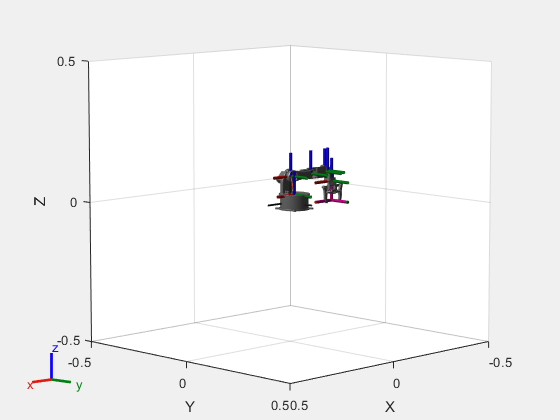

close all;

% axes = show(robot);
config = homeConfiguration(robot);
show(robot,config);

showdetails(robot);

--------------------
Robot: (7 bodies)

 Idx           Body Name              Joint Name              Joint Type           Parent Name(Idx)   Children Name(s)
 ---           ---------              ----------              ----------           ----------------   ----------------
   1        component1_1              Revolute 1                revolute               base_link(0)   component2_1(2)  
   2        component2_1              Revolute 2                revolute            component1_1(1)   component3_1(3)  
   3        component3_1              Revolute 3                revolute            component2_1(2)   component4_1(4)  
   4        component4_1              Revolute 4                revolute            component3_1(3)   component5_1(5)  
   5        component5_1              Revolute 5                revolute            component4_1(4)   component6_1(6)  
   6        component6_1              Revolute 6                revolute            component5_1(5)   end_effector(7)  
  


% config(1).JointPosition = 0;
% config(2).JointPosition = deg2rad(90);
% config(5).JointPosition = deg2rad(90);
% config(5).JointPosition = deg2rad(90);
% show(robot,config);


## Create a set of desired waypoints

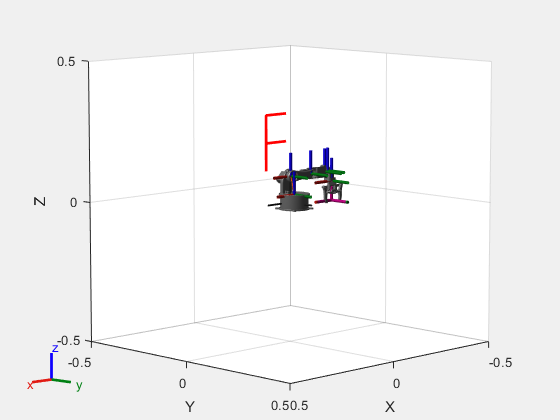

clear trajectory trj 
%% Create a trayectory F
A=[-0.0 -0.12 0.1];
B=[-0.0 -0.12 0.2];
C=[-0.1 -0.12 0.2];
D=[-0.0 -0.12 0.2];
E=[-0.0 -0.12 0.3];
F=[-0.1 -0.12 0.3];

% Generación de la trayectoria
trj=[];
[temp]=trajC(A,B,50); trj=[ trj; temp ];
[temp]=trajC(B,C,50); trj=[ trj; temp ];
[temp]=trajC(C,D,50); trj=[ trj; temp ];
[temp]=trajC(D,E,50); trj=[ trj; temp ];
[temp]=trajC(E,F,50); trj=[ trj; temp ];
trajectory=trj';

hold on
plot3(trajectory(1,:),trajectory(2,:),trajectory(3,:),'r-','LineWidth',2);

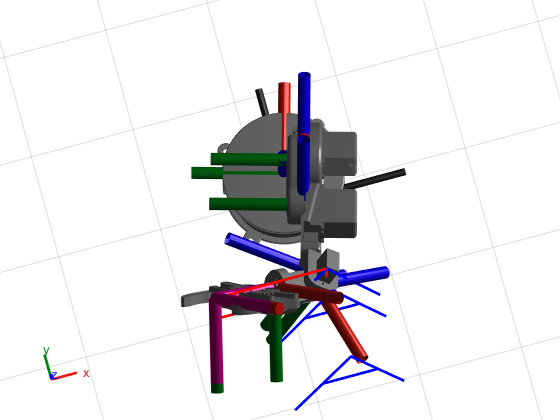

clear trajectory trj
%% Create a trayectory "A"

A1 = [-0.05, -0.12, 0.1];  % Base izquierda
A2 = [+0.00, -0.12, 0.3];   % Vértice superior
A3 = [+0.05, -0.12, 0.1];  % Base derecha
A4 = [-0.025,-0.12, 0.2]; % Punto de inicio de la barra media (izquierda)
A5 = [+0.025,-0.12, 0.2]; % Punto de fin de la barra media (derecha)

% Generación de la trayectoria
trj = [];
[temp] = trajC(A1, A2, 50); trj=[ trj; temp ];   % Línea izquierda hacia el vértice superior
[temp] = trajC(A2, A3, 50); trj=[ trj; temp ];   % Línea derecha hacia la base
[temp] = trajC(A3, A5, 50); trj=[ trj; temp ];   % Línea derecha hacia la base
[temp] = trajC(A5, A4, 50); trj=[ trj; temp ];   % Barra horizontal en el medio

% Concatenar los segmentos
trajectory = trj';

% Show
hold on
plot3(trajectory(1,:), trajectory(2,:), trajectory(3,:), 'b-', 'LineWidth', 2);

## Perform Inverse Kinematics

% Use desired weights for solution (First three are orientation, last three are translation)
clear ik configSoln solnInfo 

ik = robotics.InverseKinematics('RigidBodyTree',robot);
weights = [0 0 0 1 1 1];
initialguess = robot.homeConfiguration;

% Call inverse kinematics solver for every end-effector position using the
% previous configuration as initial guess
for idx = 1:size(trajectory,2)
    tform = trvec2tform(trajectory(:,idx)');
    
    tform(1,1)=0;
    tform(1,3)=1;
    tform(3,1)=-1;
    tform(3,3)=0;

    [configSoln(idx,:), solnInfo] = ik('end_effector',tform,weights,initialguess);
    initialguess = configSoln(idx,:);
end

## Visualize robot configurations

title('Robot waypoint tracking visualization')
axis([-0.5 0.7 -0.7 0.7 -0.5 1.0]);
for idx = 1:size(trajectory,2)
    % show(robot,configSoln(idx,:), 'PreservePlot', false,'Frames','off');
    show(robot,configSoln(idx,:), 'PreservePlot', false);
    pause(0.1)
end
hold off

## Establish the connection to the Microcontroller

% (set the COM port as required).
mc = "Esp"; % "Esp" "Arduino"
switch mc
    case "Arduino"
        puerto = 'COM3'; % Change this according to the port you are using
        baudRate = 9600; % Baud rate

    case "Esp"
        puerto = 'COM4'; 
        baudRate = 115200;
end
Mcontrol = serialport(puerto, baudRate);

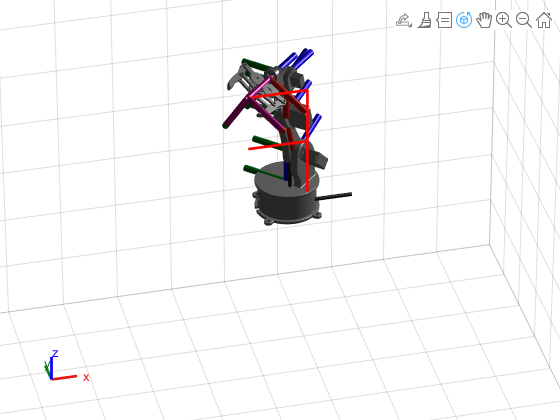

% Initialize the vectors for storing the angles
numServos = 6; % Number of servos (adjust if you have more or less servos)
anglesRad = zeros(size(configSoln, 1), numServos); % Angles in radians
anglesDeg = zeros(size(configSoln, 1), numServos); % Angles in degrees

% Calculate and store all angles before sending the data
for idx = 1:size(configSoln, 1)
    for jointIdx = 1:numServos
        jointPosition = configSoln(idx, jointIdx).JointPosition; % Extraer la posición articular en radianes
        
        % Special setting for the third axis
        if jointIdx == 3
            jointPosition = jointPosition *(-1) + (pi/2); % Ajuste específico para el rango [0, π]
        end
        
        % Convert to degrees
        angleDeg = rad2deg(jointPosition);
        
        % Store calculated values
        anglesRad(idx, jointIdx) = jointPosition; 
        anglesDeg(idx, jointIdx) = angleDeg; 
    end
end

% Send the angle rows to the microcontroller sequentially
for idx = 1:size(configSoln, 1)
    show(robot, configSoln(idx,:), 'PreservePlot', false); % Mostrar en simulación
    
    %  Create a string of angles to send
    anglesString = sprintf('%d,%d,%d,%d,%d,%d', anglesDeg(idx, 1:numServos));
    
    % Send the angles to the Microcontroller
    writeline(Mcontrol, anglesString);
    
    % General pause between each complete configuration
    pause(0.4); % Adjust this as needed
end


% Send command to move to “home” position
pause(2);
writeline(Mcontrol, 'home');
pause(0.7);

% Clear serial connection object
clear Mcontrol;

## Print final angles

disp('Ángulos de todos los servos durante la operación:');

Ángulos de todos los servos durante la operación:


for idx = 1:size(anglesRad, 1)
    fprintf('Paso %d:\n', idx);
    fprintf('   Ángulos en radianes: %s\n', mat2str(anglesRad(idx, :)));
    fprintf('   Ángulos en grados: %s\n', mat2str(anglesDeg(idx, :)));
end

Paso 1:


   Ángulos en radianes: [1.38549118829483 1.45089953810885 2.90921361021821 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976418591 83.1304200311174 166.685661567521 -1.9878466759147e-16 0 57.527958675853]


Paso 2:


   Ángulos en radianes: [1.38549118824323 1.46438276300875 2.90822369334072 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976389026 83.9029519121079 166.628943508372 -1.9878466759147e-16 0 57.527958675853]


Paso 3:


   Ángulos en radianes: [1.38549118824764 1.47758686428286 2.90694327318427 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976391551 84.6594911873772 166.555580837404 -1.9878466759147e-16 0 57.527958675853]


Paso 4:


   Ángulos en radianes: [1.3854911882553 1.49050717804292 2.90537297539246 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976395939 85.3997706358134 166.465609401354 -1.9878466759147e-16 0 57.527958675853]


Paso 5:


   Ángulos en radianes: [1.38549118826904 1.50313936136143 2.9035135615165 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976403812 86.123541426 166.359072833894 -1.9878466759147e-16 0 57.527958675853]


Paso 6:


   Ángulos en radianes: [1.38549118829423 1.51547939835242 2.90136592526222 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976418244 86.8305734646191 166.236022340594 -1.9878466759147e-16 0 57.527958675853]


Paso 7:


   Ángulos en radianes: [1.38549118824068 1.52752360464512 2.89893108811418 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 87.5206556527757 166.09651644821 -1.9878466759147e-16 0 57.527958675853]


Paso 8:


   Ángulos en radianes: [1.38549118824081 1.53926862946644 2.89621019414299 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387638 88.1935960053134 165.940620707158 -1.9878466759147e-16 0 57.527958675853]


Paso 9:


   Ángulos en radianes: [1.38549118824223 1.55071145731674 2.89320450470528 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976388452 88.8492217468307 165.76840738785 -1.9878466759147e-16 0 57.527958675853]


Paso 10:


   Ángulos en radianes: [1.38549118824481 1.561849406807 2.88991539216024 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976389933 89.4873792450524 165.579955120676 -1.9878466759147e-16 0 57.527958675853]


Paso 11:


   Ángulos en radianes: [1.38549118824968 1.57268012850616 2.88634433335887 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.382797639272 90.1079338874951 165.375348522964 -1.9878466759147e-16 0 57.527958675853]


Paso 12:


   Ángulos en radianes: [1.38549118826006 1.5832016011473 2.8824929026444 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976398668 90.7107698640946 165.154677797938 -1.9878466759147e-16 0 57.527958675853]


Paso 13:


   Ángulos en radianes: [1.38549118824068 1.59341212645594 2.87836276449109 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 91.2957898708914 164.918038312948 -1.9878466759147e-16 0 57.527958675853]


Paso 14:


   Ángulos en radianes: [1.38549118824093 1.60331032240541 2.87395566572399 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387707 91.8629147235895 164.665530153695 -1.9878466759147e-16 0 57.527958675853]


Paso 15:


   Ángulos en radianes: [1.38549118824212 1.61289511563258 2.86927342762372 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976388391 92.4120829230115 164.397257671874 -1.9878466759147e-16 0 57.527958675853]


Paso 16:


   Ángulos en radianes: [1.3854911882447 1.62216573230969 2.86431793762007 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976389868 92.9432501320938 164.113329009246 -1.9878466759147e-16 0 57.527958675853]


Paso 17:


   Ángulos en radianes: [1.38549118825062 1.63112168816224 2.85909114088442 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976393259 93.4563886039503 163.813855615921 -1.9878466759147e-16 0 57.527958675853]


Paso 18:


   Ángulos en radianes: [1.38549118824068 1.63976277752837 2.8535950317607 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 93.9514865550252 163.498951759388 -1.9878466759147e-16 0 57.527958675853]


Paso 19:


   Ángulos en radianes: [1.38549118824098 1.64808906148937 2.8478316450563 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387738 94.4285474850174 163.168734025524 -1.9878466759147e-16 0 57.527958675853]


Paso 20:


   Ángulos en radianes: [1.38549118824173 1.65610085546411 2.84180304734628 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976388169 94.8875894660986 162.823320820358 -1.9878466759147e-16 0 57.527958675853]


Paso 21:


   Ángulos en radianes: [1.38549118824256 1.66379871601982 2.83551132817611 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976388639 95.3286443872214 162.462831866026 -1.9878466759147e-16 0 57.527958675853]


Paso 22:


   Ángulos en radianes: [1.38549118824203 1.67118342725983 2.8289585913131 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976388338 95.7517571741967 162.087387699516 -1.9878466759147e-16 0 57.527958675853]


Paso 23:


   Ángulos en radianes: [1.3854911882407 1.67825598678493 2.82214694602899 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387576 96.1569849853397 161.697109173196 -1.9878466759147e-16 0 57.527958675853]


Paso 24:


   Ángulos en radianes: [1.38549118824074 1.6850175913508 2.81507849845227 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.38279763876 96.5443963897003 161.29211695934 -1.9878466759147e-16 0 57.527958675853]


Paso 25:


   Ángulos en radianes: [1.38549123347319 1.69146955427009 2.80775530224911 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3828002303884 96.9140666345507 160.872528724353 -1.9878466759147e-16 0 57.527958675853]


Paso 26:


   Ángulos en radianes: [1.38549122270932 1.69761354818204 2.80017950874381 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827996136642 97.2660915550598 160.438467730037 -1.9878466759147e-16 0 57.527958675853]


Paso 27:


   Ángulos en radianes: [1.38549118879797 1.7034513119124 2.79235317319143 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976706868 97.6005707786038 159.990051733832 -1.9878466759147e-16 0 57.527958675853]


Paso 28:


   Ángulos en radianes: [1.38549118824068 1.70898454750608 2.78427822216702 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 97.9176018251732 159.527391120358 -1.9878466759147e-16 0 57.527958675853]


Paso 29:


   Ángulos en radianes: [1.38549118824068 1.71421527507749 2.77595665315717 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 98.2173004387975 159.050600337167 -1.9878466759147e-16 0 57.527958675853]


Paso 30:


   Ángulos en radianes: [1.38549118824068 1.71914559054066 2.76739038243059 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 98.4997867065051 158.559789178367 -1.9878466759147e-16 0 57.527958675853]


Paso 31:


   Ángulos en radianes: [1.38549119920772 1.72377761161812 2.75858123565117 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827982671215 98.7651819648594 158.055062246796 -1.9878466759147e-16 0 57.527958675853]


Paso 32:


   Ángulos en radianes: [1.3854911900146 1.7281137626697 2.74953106622353 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827977403943 99.0136251194459 157.536525734713 -1.9878466759147e-16 0 57.527958675853]


Paso 33:


   Ángulos en radianes: [1.38549118824068 1.73215627766817 2.74024153345808 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 99.2452441674771 157.004274713605 -1.9878466759147e-16 0 57.527958675853]


Paso 34:


   Ángulos en radianes: [1.38549118824068 1.73590751857899 2.73071426134782 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 99.4601744396038 156.458402231414 -1.9878466759147e-16 0 57.527958675853]


Paso 35:


   Ángulos en radianes: [1.38549118824068 1.73936994775942 2.72095079686306 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 99.6585570185054 155.898996923011 -1.9878466759147e-16 0 57.527958675853]


Paso 36:


   Ángulos en radianes: [1.38549119986333 1.74254596043033 2.71095256014912 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827983046852 99.8405291402284 155.32614015673 -1.9878466759147e-16 0 57.527958675853]


Paso 37:


   Ángulos en radianes: [1.38549118824068 1.74543823650054 2.70072095063892 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.006244352238 154.739912114169 -1.9878466759147e-16 0 57.527958675853]


Paso 38:


   Ángulos en radianes: [1.38549118824068 1.74804906060617 2.69025713356243 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.155833554542 154.14037955809 -1.9878466759147e-16 0 57.527958675853]


Paso 39:


   Ángulos en radianes: [1.38549118824068 1.75038097832266 2.67956223983368 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.289442597868 153.527607285092 -1.9878466759147e-16 0 57.527958675853]


Paso 40:


   Ángulos en radianes: [1.38549118824068 1.75243645087051 2.6686372559677 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387564 100.407212499766 152.901651818322 -1.9878466759147e-16 0 57.527958675853]


Paso 41:


   Ángulos en radianes: [1.38549118824068 1.75421791090644 2.65748303798975 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387563 100.509282641195 152.262562204417 -1.9878466759147e-16 0 57.527958675853]


Paso 42:


   Ángulos en radianes: [1.38549118824068 1.75572775184893 2.64610030463961 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.595790154936 151.610379624131 -1.9878466759147e-16 0 57.527958675853]


Paso 43:


   Ángulos en radianes: [1.38549118824068 1.75696831750818 2.63448963050135 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.66686933142 150.945136998707 -1.9878466759147e-16 0 57.527958675853]


Paso 44:


   Ángulos en radianes: [1.38549118824068 1.75794189199492 2.62265143901936 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.722651040552 150.266858589721 -1.9878466759147e-16 0 57.527958675853]


Paso 45:


   Ángulos en radianes: [1.38549118824068 1.75865068987923 2.61058599535815 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.76326216785 149.575559589981 -1.9878466759147e-16 0 57.527958675853]


Paso 46:


   Ángulos en radianes: [1.38549118824068 1.75909684656588 2.59829339906003 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387564 100.788825062997 148.871245702841 -1.9878466759147e-16 0 57.527958675853]


Paso 47:


   Ángulos en radianes: [1.38549118824068 1.75928240884937 2.58577357645069 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387563 100.799456998678 148.153912707073 -1.9878466759147e-16 0 57.527958675853]


Paso 48:


   Ángulos en radianes: [1.38549118824068 1.75920932560747 2.57302627273868 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387563 100.795269637364 147.423546004203 -1.9878466759147e-16 0 57.527958675853]


Paso 49:


   Ángulos en radianes: [1.38549118824068 1.75887943858861 2.56005104375015 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.776368503467 146.680120144945 -1.9878466759147e-16 0 57.527958675853]


Paso 50:


   Ángulos en radianes: [1.38549118824068 1.75829447324413 2.54684724723486 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.742852458067 145.923598331069 -1.9878466759147e-16 0 57.527958675853]


Paso 51:


   Ángulos en radianes: [1.38549118824068 1.75745602955224 2.5334140336739 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.694813173162 145.153931888728 -1.9878466759147e-16 0 57.527958675853]


Paso 52:


   Ángulos en radianes: [1.38549118824068 1.75745602955224 2.5334140336739 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.694813173162 145.153931888728 -1.9878466759147e-16 0 57.527958675853]


Paso 53:


   Ángulos en radianes: [1.37136426600445 1.75732539018782 2.53329878040421 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [78.5733846171109 100.687328088943 145.1473283628 -1.9878466759147e-16 0 57.527958675853]


Paso 54:


   Ángulos en radianes: [1.35728033209443 1.75690453756859 2.53292742136759 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [77.7664346451254 100.663215010064 145.126051057318 -1.9878466759147e-16 0 57.527958675853]


Paso 55:


   Ángulos en radianes: [1.34324493138066 1.75619377591105 2.5322999962504 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [76.9622654204516 100.622491366847 145.090102246142 -1.9878466759147e-16 0 57.527958675853]


Paso 56:


   Ángulos en radianes: [1.32926351417467 1.75519361762132 2.53141657170825 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [76.1611892229366 100.565186518001 145.039485748359 -1.9878466759147e-16 0 57.527958675853]


Paso 57:


   Ángulos en radianes: [1.31534144977241 1.75390472835781 2.53027716963966 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [75.363513690578 100.491338602942 144.97420281866 -1.9878466759147e-16 0 57.527958675853]


Paso 58:


   Ángulos en radianes: [1.30148388902477 1.75232818490322 2.52888211643606 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [74.5695339453923 100.401009316775 144.894272157898 -1.9878466759147e-16 0 57.527958675853]


Paso 59:


   Ángulos en radianes: [1.28769599756068 1.75046495608265 2.52723135255379 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [73.7795459561152 100.294254169089 144.799690354471 -1.9878466759147e-16 0 57.527958675853]


Paso 60:


   Ángulos en radianes: [1.27398270855513 1.74831638252952 2.52532508302515 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [72.9938323728542 100.171149972521 144.690469155865 -1.9878466759147e-16 0 57.527958675853]


Paso 61:


   Ángulos en radianes: [1.26034882488243 1.74588403890102 2.52316356875044 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [72.212668380036 100.031786948282 144.566623510567 -1.9878466759147e-16 0 57.527958675853]


Paso 62:


   Ángulos en radianes: [1.24679899297826 1.74316954443826 2.52074694500386 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [71.4363201988153 99.8762578720544 144.428161169217 -1.9878466759147e-16 0 57.527958675853]


Paso 63:


   Ángulos en radianes: [1.23333768904485 1.74017477810467 2.51807545267007 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [70.665044296688 99.7046704005119 144.275095933489 -1.9878466759147e-16 0 57.527958675853]


Paso 64:


   Ángulos en radianes: [1.2199692147513 1.73690177087689 2.51514933074015 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [69.8990871411386 99.5171409000446 144.107441496564 -1.9878466759147e-16 0 57.527958675853]


Paso 65:


   Ángulos en radianes: [1.20669769026569 1.73335271115493 2.51196882805645 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [69.138684800409 99.3137947567364 143.925212116058 -1.9878466759147e-16 0 57.527958675853]


Paso 66:


   Ángulos en radianes: [1.19352704850293 1.72952993714423 2.50853420184297 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [68.3840626139239 99.0947659398912 143.728422529821 -1.9878466759147e-16 0 57.527958675853]


Paso 67:


   Ángulos en radianes: [1.18046103035222 1.72543592747256 2.50484571466835 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [67.6354349188467 98.8601964644183 143.517087781927 -1.9878466759147e-16 0 57.527958675853]


Paso 68:


   Ángulos en radianes: [1.16750318079906 1.72107329119929 2.50090363103637 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [66.8930048278852 98.6102358184092 143.291223027327 -1.9878466759147e-16 0 57.527958675853]


Paso 69:


   Ángulos en radianes: [1.15465684592063 1.71644475741108 2.49670821376272 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [66.1569640571396 98.3450403670116 143.050843324251 -1.9878466759147e-16 0 57.527958675853]


Paso 70:


   Ángulos en radianes: [1.14192517074207 1.71155316445342 2.49225972013637 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [65.4274928032767 98.0647727354413 142.79596341427 -1.9878466759147e-16 0 57.527958675853]


Paso 71:


   Ángulos en radianes: [1.12931109793843 1.70640144880485 2.48755839781293 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [64.7047596691573 97.7696011715267 142.526597487006 -1.9878466759147e-16 0 57.527958675853]


Paso 72:


   Ángulos en radianes: [1.11681735547018 1.70099272091269 2.48260458534975 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [63.9889209554029 97.4597038907714 142.242764940366 -1.9878466759147e-16 0 57.527958675853]


Paso 73:


   Ángulos en radianes: [1.1044464990092 1.69532994707335 2.47739834058455 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [63.280123091227 97.1352508494403 141.944469088209 -1.9878466759147e-16 0 57.527958675853]


Paso 74:


   Ángulos en radianes: [1.09220085609923 1.68941634838563 2.47193992683607 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [62.578499435061 96.7964266028998 141.631725017584 -1.9878466759147e-16 0 57.527958675853]


Paso 75:


   Ángulos en radianes: [1.08008256235069 1.68325514118905 2.46622951234338 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [61.8841723483699 96.4434154338301 141.304542367883 -1.9878466759147e-16 0 57.527958675853]


Paso 76:


   Ángulos en radianes: [1.06809355591807 1.67684958164056 2.46026723253446 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [61.1972528792258 96.0764039062817 140.962928898556 -1.9878466759147e-16 0 57.527958675853]


Paso 77:


   Ángulos en radianes: [1.05623558049301 1.6702029536751 2.45405318461304 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [60.5178409338001 95.6955801758675 140.606890178966 -1.9878466759147e-16 0 57.527958675853]


Paso 78:


   Ángulos en radianes: [1.04451018886194 1.66331855693515 2.44758742188818 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [59.8460254802015 95.3011332981744 140.236429263499 -1.9878466759147e-16 0 57.527958675853]


Paso 79:


   Ángulos en radianes: [1.03291874698082 1.65619969468408 2.44086994782055 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [59.1818847819422 94.8932525362533 139.851546350435 -1.9878466759147e-16 0 57.527958675853]


Paso 80:


   Ángulos en radianes: [1.02146243851977 1.64884966170748 2.43390070974712 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [58.5254866583242 94.4721266674119 139.452238422405 -1.9878466759147e-16 0 57.527958675853]


Paso 81:


   Ángulos en radianes: [1.01014226983124 1.64127173219459 2.42667959223161 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [57.876888769095 94.0379432888757 139.038498865399 -1.9878466759147e-16 0 57.527958675853]


Paso 82:


   Ángulos en radianes: [0.998959075297444 1.63346914758319 2.41920640997207 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [57.2361389208349 93.5908881213489 138.610317062395 -1.9878466759147e-16 0 57.527958675853]


Paso 83:


   Ángulos en radianes: [0.987913495787674 1.62544520698194 2.41148098118488 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [56.6032738326489 93.1311501898335 138.16768259796 -1.9878466759147e-16 0 57.527958675853]


Paso 84:


   Ángulos en radianes: [0.977006080526561 1.6172029070117 2.40350285020054 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [55.9783249727906 92.6589011880583 137.710569364155 -1.9878466759147e-16 0 57.527958675853]


Paso 85:


   Ángulos en radianes: [0.96623716297244 1.60874539261366 2.39527163473799 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [55.3613114470151 92.1743213078793 137.238955457888 -1.9878466759147e-16 0 57.527958675853]


Paso 86:


   Ángulos en radianes: [0.955606946593305 1.60007566855801 2.38678680659103 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [54.7522449131798 91.6775827099475 136.752810615174 -1.9878466759147e-16 0 57.527958675853]


Paso 87:


   Ángulos en radianes: [0.94511549287175 1.59119665159076 2.3780477313434 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [54.1511288939779 91.1688525114992 136.252098486637 -1.9878466759147e-16 0 57.527958675853]


Paso 88:


   Ángulos en radianes: [0.934762727786079 1.58211115949112 2.36905365972721 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [53.5579591482786 90.6482921593901 135.736776142391 -1.9878466759147e-16 0 57.527958675853]


Paso 89:


   Ángulos en radianes: [0.924548454486056 1.57282186331121 2.35980370069834 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [52.9727243973941 90.1160546936344 135.206792529368 -1.9878466759147e-16 0 57.527958675853]


Paso 90:


   Ángulos en radianes: [0.914472338254425 1.56333140057959 2.3502968684223 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [52.3954054634383 89.5722912334864 134.662091163412 -1.9878466759147e-16 0 57.527958675853]


Paso 91:


   Ángulos en radianes: [0.904533928951738 1.55364229839218 2.34053205677168 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [51.8259765553209 89.0171465708766 134.102608668091 -1.9878466759147e-16 0 57.527958675853]


Paso 92:


   Ángulos en radianes: [0.894732697116955 1.54375672590383 2.33050788100981 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [51.2644073371585 88.4507449892237 133.528265703839 -1.9878466759147e-16 0 57.527958675853]


Paso 93:


   Ángulos en radianes: [0.885067980118967 1.53367690491982 2.32022290313922 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [50.7106598429854 87.8732137885925 132.938979879468 -1.9878466759147e-16 0 57.527958675853]


Paso 94:


   Ángulos en radianes: [0.87553902785846 1.52340483300002 2.30967547464097 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [50.1646910952768 87.2846674207332 132.334656741802 -1.9878466759147e-16 0 57.527958675853]


Paso 95:


   Ángulos en radianes: [0.866144999906627 1.51294233305824 2.2988637561054 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [49.6264529410088 86.6852103309131 131.715190900431 -1.9878466759147e-16 0 57.527958675853]


Paso 96:


   Ángulos en radianes: [0.856884971611147 1.50229104215881 2.28778570335541 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [49.0958924015061 86.0749363160096 131.080465232633 -1.9878466759147e-16 0 57.527958675853]


Paso 97:


   Ángulos en radianes: [0.847757940054675 1.49145240002778 2.27643905254654 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [48.5729520138375 85.4539278662494 130.430350029677 -1.9878466759147e-16 0 57.527958675853]


Paso 98:


   Ángulos en radianes: [0.838762829851708 1.48042763719387 2.26482130412276 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [48.0575701629525 84.8222554857333 129.764702077549 -1.9878466759147e-16 0 57.527958675853]


Paso 99:


   Ángulos en radianes: [0.8298984987719 1.46921776266313 2.25292970548983 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [47.5496814038728 84.1799769862507 129.083363664219 -1.9878466759147e-16 0 57.527958675853]


Paso 100:


   Ángulos en radianes: [0.821163743179962 1.45782355101923 2.24076123224932 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [47.0492167733765 83.5271367481767 128.38616150442 -1.9878466759147e-16 0 57.527958675853]


Paso 101:


   Ángulos en radianes: [0.812557303284219 1.44624552882672 2.22831256781383 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [46.5561040907174 82.8637649414366 127.672905571691 -1.9878466759147e-16 0 57.527958675853]


Paso 102:


   Ángulos en radianes: [0.804077868187692 1.43448396019868 2.21558008119827 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [46.0702682470313 82.1898766985967 126.943387825913 -1.9878466759147e-16 0 57.527958675853]


Paso 103:


   Ángulos en radianes: [0.804077868187692 1.43448396019868 2.21558008119827 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [46.0702682470313 82.1898766985967 126.943387825913 -1.9878466759147e-16 0 57.527958675853]


Paso 104:


   Ángulos en radianes: [0.812557334531463 1.4462455757126 2.22831255837284 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [46.5561058810526 82.8637676277999 127.672905030763 -1.9878466759147e-16 0 57.527958675853]


Paso 105:


   Ángulos en radianes: [0.821163776249094 1.45782360180043 2.2407612246407 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [47.0492186680981 83.5271396577252 128.386161068478 -1.9878466759147e-16 0 57.527958675853]


Paso 106:


   Ángulos en radianes: [0.829898533761549 1.4692178176316 2.25292969992474 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [47.549683408632 84.179980135712 129.083363345363 -1.9878466759147e-16 0 57.527958675853]


Paso 107:


   Ángulos en radianes: [0.838762866859192 1.48042769664329 2.26482130082613 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [48.0575722833251 84.8222588919341 129.764701888666 -1.9878466759147e-16 0 57.527958675853]


Paso 108:


   Ángulos en radianes: [0.847757979176167 1.49145246425474 2.27643905175714 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [48.5729542553339 85.4539315461829 130.430349984447 -1.9878466759147e-16 0 57.527958675853]


Paso 109:


   Ángulos en radianes: [0.856885012940668 1.50229111145957 2.28778570532447 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [49.0958947695132 86.0749402866507 131.080465345452 -1.9878466759147e-16 0 57.527958675853]


Paso 110:


   Ángulos en radianes: [0.866145043534951 1.51294240772506 2.29886376109481 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [49.6264554407277 86.6852146090068 131.715191186304 -1.9878466759147e-16 0 57.527958675853]


Paso 111:


   Ángulos en radianes: [0.875539073871937 1.52340491331697 2.30967548292101 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [50.1646937316548 87.2846720225556 132.334657216214 -1.9878466759147e-16 0 57.527958675853]


Paso 112:


   Ángulos en radianes: [0.885067981474074 1.53367690397497 2.3202229004941 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [50.7106599206274 87.8732137344563 132.938979727915 -1.9878466759147e-16 0 57.527958675853]


Paso 113:


   Ángulos en radianes: [0.894732698571764 1.54375672495926 2.33050787827956 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [51.2644074205129 88.4507449351036 133.528265547407 -1.9878466759147e-16 0 57.527958675853]


Paso 114:


   Ángulos en radianes: [0.904533930511293 1.55364229745178 2.34053205395837 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [51.8259766446768 89.0171465169958 134.102608506901 -1.9878466759147e-16 0 57.527958675853]


Paso 115:


   Ángulos en radianes: [0.914472330825367 1.56333146023984 2.3502968981198 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [52.3954050377847 89.5722946517666 134.662092864953 -1.9878466759147e-16 0 57.527958675853]


Paso 116:


   Ángulos en radianes: [0.924548450130777 1.57282189930598 2.35980371556096 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [52.972724147855 90.1160567559828 135.206793380933 -1.9878466759147e-16 0 57.527958675853]


Paso 117:


   Ángulos en radianes: [0.934762729688497 1.58211115858959 2.36905365668533 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [53.5579592572791 90.6482921077365 135.736775968104 -1.9878466759147e-16 0 57.527958675853]


Paso 118:


   Ángulos en radianes: [0.945115494896854 1.59119665071179 2.37804772823537 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [54.1511290100078 91.1688524611377 136.25209830856 -1.9878466759147e-16 0 57.527958675853]


Paso 119:


   Ángulos en radianes: [0.955606948744519 1.60007566770664 2.3867868034235 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [54.7522450364353 91.6775826611678 136.752810433687 -1.9878466759147e-16 0 57.527958675853]


Paso 120:


   Ángulos en radianes: [0.966237165252599 1.60874539179501 2.39527163151853 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [55.3613115776586 92.174321260974 137.238955273427 -1.9878466759147e-16 0 57.527958675853]


Paso 121:


   Ángulos en radianes: [0.977006082937832 1.61720290623085 2.40350284693765 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [55.9783251109463 92.6589011433186 137.710569177205 -1.9878466759147e-16 0 57.527958675853]


Paso 122:


   Ángulos en radianes: [0.987913498331485 1.62544520624386 2.41148097788794 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [56.6032739783986 93.1311501475449 138.16768240906 -1.9878466759147e-16 0 57.527958675853]


Paso 123:


   Ángulos en radianes: [0.998959059591155 1.63346921009627 2.41920645459623 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [57.2361380209309 93.5908917030844 138.610319619171 -1.9878466759147e-16 0 57.527958675853]


Paso 124:


   Ángulos en radianes: [1.01014226024515 1.64127177026588 2.42667961716097 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [57.8768882198528 94.0379454701999 139.038500293746 -1.9878466759147e-16 0 57.527958675853]


Paso 125:


   Ángulos en radianes: [1.02146243311141 1.64884968476203 2.43390072305562 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [58.525486348448 94.4721279883406 139.452239184926 -1.9878466759147e-16 0 57.527958675853]


Paso 126:


   Ángulos en radianes: [1.03291874443507 1.65619970857546 2.44086995430898 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [59.1818846360814 94.8932533321708 139.851546722195 -1.9878466759147e-16 0 57.527958675853]


Paso 127:


   Ángulos en radianes: [1.04451018829063 1.66331856525788 2.44758742438444 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [59.8460254474682 95.301133775032 140.236429406524 -1.9878466759147e-16 0 57.527958675853]


Paso 128:


   Ángulos en radianes: [1.05623558129635 1.67020295862187 2.45405318477673 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [60.5178409798278 95.6955804592963 140.606890188345 -1.9878466759147e-16 0 57.527958675853]


Paso 129:


   Ángulos en radianes: [1.06809355768948 1.67684958454658 2.46026723134205 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [61.1972529807204 96.0764040727844 140.962928830236 -1.9878466759147e-16 0 57.527958675853]


Paso 130:


   Ángulos en radianes: [1.08008256481227 1.68325514286993 2.46622951037475 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [61.8841724894085 96.4434155301375 141.304542255088 -1.9878466759147e-16 0 57.527958675853]


Paso 131:


   Ángulos en radianes: [1.09220085905843 1.68941634934319 2.47193992444107 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [62.578499604611 96.796426657764 141.631724880361 -1.9878466759147e-16 0 57.527958675853]


Paso 132:


   Ángulos en radianes: [1.1044465023303 1.69532994761934 2.47739833797887 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [63.2801232815118 97.1352508807231 141.944468938914 -1.9878466759147e-16 0 57.527958675853]


Paso 133:


   Ángulos en radianes: [1.11681735905591 1.70099272124245 2.48260458266957 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [63.9889211608502 97.459703909665 142.242764786804 -1.9878466759147e-16 0 57.527958675853]


Paso 134:


   Ángulos en radianes: [1.1293110938141 1.70640150560116 2.48755846258762 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [64.7047594328508 97.769604425716 142.526601198323 -1.9878466759147e-16 0 57.527958675853]


Paso 135:


   Ángulos en radianes: [1.14192516961413 1.7115531998059 2.49225975913039 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [65.4274927386505 98.0647747609895 142.795965648462 -1.9878466759147e-16 0 57.527958675853]


Paso 136:


   Ángulos en radianes: [1.1546568468736 1.71644477844582 2.49670823573067 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [66.1569641117406 98.3450415722134 143.050844582921 -1.9878466759147e-16 0 57.527958675853]


Paso 137:


   Ángulos en radianes: [1.16750318313573 1.72107330317903 2.50090364235242 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [66.8930049617665 98.6102365047977 143.291223675689 -1.9878466759147e-16 0 57.527958675853]


Paso 138:


   Ángulos en radianes: [1.1804610335631 1.72543593410667 2.50484571976937 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [67.6354351028166 98.8601968445248 143.517088074194 -1.9878466759147e-16 0 57.527958675853]


Paso 139:


   Ángulos en radianes: [1.19352705224071 1.72952994087993 2.50853420362518 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [68.384062828083 99.094766153931 143.728422631934 -1.9878466759147e-16 0 57.527958675853]


Paso 140:


   Ángulos en radianes: [1.20669769431623 1.73335271348719 2.51196882827333 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [69.1386850324878 99.3137948903653 143.925212128485 -1.9878466759147e-16 0 57.527958675853]


Paso 141:


   Ángulos en radianes: [1.21996921899952 1.73690177266779 2.51514933039401 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [69.8990873845437 99.5171410026555 144.107441476732 -1.9878466759147e-16 0 57.527958675853]


Paso 142:


   Ángulos en radianes: [1.23333769343711 1.7401747798984 2.51807545238509 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [70.6650445483461 99.7046705032851 144.275095917161 -1.9878466759147e-16 0 57.527958675853]


Paso 143:


   Ángulos en radianes: [1.24679899746921 1.74316954689745 2.52074694552366 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [71.4363204561281 99.8762580129559 144.428161199 -1.9878466759147e-16 0 57.527958675853]


Paso 144:


   Ángulos en radianes: [1.26034882926507 1.74588404459057 2.52316357289209 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [72.2126686311427 100.03178727427 144.566623747866 -1.9878466759147e-16 0 57.527958675853]


Paso 145:


   Ángulos en radianes: [1.27398271180937 1.74831641146733 2.52532511205196 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [72.9938325593083 100.171151630535 144.690470818979 -1.9878466759147e-16 0 57.527958675853]


Paso 146:


   Ángulos en radianes: [1.28769599545323 1.75046495922082 2.52723135698238 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [73.7795458353673 100.294254348893 144.79969060821 -1.9878466759147e-16 0 57.527958675853]


Paso 147:


   Ángulos en radianes: [1.30148388590692 1.75232818798273 2.52888212163938 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [74.5695337667522 100.401009493218 144.894272456026 -1.9878466759147e-16 0 57.527958675853]


Paso 148:


   Ángulos en radianes: [1.31534142454247 1.75390478108449 2.5302772406773 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [75.3635122450092 100.491341623958 144.974206888817 -1.9878466759147e-16 0 57.527958675853]


Paso 149:


   Ángulos en radianes: [1.32926351387242 1.75519361744659 2.53141657174647 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [76.161189205619 100.565186507989 145.039485750549 -1.9878466759147e-16 0 57.527958675853]


Paso 150:


   Ángulos en radianes: [1.34324493385982 1.75619377488037 2.53229999472859 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [76.9622655624972 100.622491307794 145.090102158949 -1.9878466759147e-16 0 57.527958675853]


Paso 151:


   Ángulos en radianes: [1.35728033494214 1.7569045377302 2.53292742078099 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [77.7664348082872 100.663215019323 145.126051023708 -1.9878466759147e-16 0 57.527958675853]


Paso 152:


   Ángulos en radianes: [1.37136426600445 1.75732539018782 2.53329878040421 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [78.5733846171108 100.687328088943 145.1473283628 -1.9878466759147e-16 0 57.527958675853]


Paso 153:


   Ángulos en radianes: [1.38549122826848 1.75745600781266 2.53341399540108 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827999321802 100.694811927576 145.153929695857 -1.9878466759147e-16 0 57.527958675853]


Paso 154:


   Ángulos en radianes: [1.38549122826848 1.75745600781266 2.53341399540108 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827999321802 100.694811927576 145.153929695857 -1.9878466759147e-16 0 57.527958675853]


Paso 155:


   Ángulos en radianes: [1.38549118824068 1.75636557277612 2.51975033651274 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.632334602149 144.371059708849 -1.9878466759147e-16 0 57.527958675853]


Paso 156:


   Ángulos en radianes: [1.38549118824068 1.75502442409344 2.50585486173596 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.555492442932 143.574907649809 -1.9878466759147e-16 0 57.527958675853]


Paso 157:


   Ángulos en radianes: [1.38549118824068 1.75343375102931 2.4917260766913 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.464353589772 142.765387897102 -1.9878466759147e-16 0 57.527958675853]


Paso 158:


   Ángulos en radianes: [1.38549118824068 1.75159455761868 2.47736219806115 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.358975569635 141.942398274157 -1.9878466759147e-16 0 57.527958675853]


Paso 159:


   Ángulos en radianes: [1.38549118824068 1.74950767421708 2.46276117886801 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.239405958387 141.1058214978 -1.9878466759147e-16 0 57.527958675853]


Paso 160:


   Ángulos en radianes: [1.38549118824068 1.7471737468711 2.44792069438794 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 100.105681771773 140.255524371163 -1.9878466759147e-16 0 57.527958675853]


Paso 161:


   Ángulos en radianes: [1.38549118824068 1.74459322615095 2.43283812683062 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 99.9578288255616 139.391356905908 -1.9878466759147e-16 0 57.527958675853]


Paso 162:


   Ángulos en radianes: [1.38549118824068 1.74176635533696 2.41751054862773 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 99.7958610586915 138.513151364725 -1.9878466759147e-16 0 57.527958675853]


Paso 163:


   Ángulos en radianes: [1.38549118824068 1.73869315784032 2.40193470415075 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 99.6197798125237 137.620721213842 -1.9878466759147e-16 0 57.527958675853]


Paso 164:


   Ángulos en radianes: [1.38549118824068 1.73537342372382 2.38610698965618 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 99.4295730585427 136.713859973965 -1.9878466759147e-16 0 57.527958675853]


Paso 165:


   Ángulos en radianes: [1.38549118824068 1.73180669517261 2.37002343122839 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 99.2252145658898 135.7923399565 -1.9878466759147e-16 0 57.527958675853]


Paso 166:


   Ángulos en radianes: [1.38549118824068 1.72799225074538 2.35367966045828 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 99.0066629990223 134.855910870044 -1.9878466759147e-16 0 57.527958675853]


Paso 167:


   Ángulos en radianes: [1.38549118824068 1.72392908821399 2.33707088755808 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 98.7738609344976 133.904298279972 -1.9878466759147e-16 0 57.527958675853]


Paso 168:


   Ángulos en radianes: [1.38549118824068 1.71961590577278 2.32019187156777 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 98.5267337843466 132.937201901393 -1.9878466759147e-16 0 57.527958675853]


Paso 169:


   Ángulos en radianes: [1.38549118824068 1.71505108136728 2.30303688725594 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 98.2651886116928 131.954293702712 -1.9878466759147e-16 0 57.527958675853]


Paso 170:


   Ángulos en radianes: [1.38549118824068 1.71023264985392 2.28559968825507 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 97.9891128221046 130.955215793432 -1.9878466759147e-16 0 57.527958675853]


Paso 171:


   Ángulos en radianes: [1.38549118824068 1.70515827765794 2.26787346589634 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 97.6983727115967 129.939578065566 -1.9878466759147e-16 0 57.527958675853]


Paso 172:


   Ángulos en radianes: [1.38549118824068 1.69982523454206 2.24985080311946 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 97.3928118490955 128.906955552864 -1.9878466759147e-16 0 57.527958675853]


Paso 173:


   Ángulos en radianes: [1.38549118824068 1.6942303620339 2.23152362272559 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 97.072249267464 127.85688546592 -1.9878466759147e-16 0 57.527958675853]


Paso 174:


   Ángulos en radianes: [1.38549118824068 1.6883700379814 2.21288312911108 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 96.7364774326766 126.788863853768 -1.9878466759147e-16 0 57.527958675853]


Paso 175:


   Ángulos en radianes: [1.38549118824068 1.68224013661006 2.19391974246243 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 96.3852599552674 125.702341833526 -1.9878466759147e-16 0 57.527958675853]


Paso 176:


   Ángulos en radianes: [1.38549118824068 1.67583598333942 2.17462302420069 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 96.0183290015051 124.596721318675 -1.9878466759147e-16 0 57.527958675853]


Paso 177:


   Ángulos en radianes: [1.38549118824068 1.66915230347333 2.15498159222766 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 95.6353823535615 123.471350163027 -1.9878466759147e-16 0 57.527958675853]


Paso 178:


   Ángulos en radianes: [1.38549118824068 1.66218316370241 2.1349830242366 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 95.2360800578509 122.325516620834 -1.9878466759147e-16 0 57.527958675853]


Paso 179:


   Ángulos en radianes: [1.38549118824068 1.65492190513871 2.11461374698998 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 94.8200405881978 121.158443002871 -1.9878466759147e-16 0 57.527958675853]


Paso 180:


   Ángulos en radianes: [1.38549125449654 1.64736107701469 2.09385890597866 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3828014349376 94.3868370470674 119.969278208457 -1.9878466759147e-16 0 57.527958675853]


Paso 181:


   Ángulos en radianes: [1.38549118824068 1.63949229435634 2.07270223362924 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 93.9359890108383 118.757090174294 -1.9878466759147e-16 0 57.527958675853]


Paso 182:


   Ángulos en radianes: [1.38549122196732 1.63130626970467 2.05112586038804 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827995711506 93.4669643473077 117.520855050374 -1.9878466759147e-16 0 57.527958675853]


Paso 183:


   Ángulos en radianes: [1.38549118824068 1.62279244589588 2.02911008646793 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 92.9791581755459 116.259444122038 -1.9878466759147e-16 0 57.527958675853]


Paso 184:


   Ángulos en radianes: [1.38549119971476 1.61393921020354 2.0066332660806 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827982961731 92.4719051353401 114.971617176971 -1.9878466759147e-16 0 57.527958675853]


Paso 185:


   Ángulos en radianes: [1.3854912409547 1.60473337906639 1.98367136313924 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3828006590475 91.9444498642716 113.655997048841 -1.9878466759147e-16 0 57.527958675853]


Paso 186:


   Ángulos en radianes: [1.38549118824068 1.59516010904704 1.96019776357018 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 91.3959418960233 112.311058863554 -1.9878466759147e-16 0 57.527958675853]


Paso 187:


   Ángulos en radianes: [1.38549119160793 1.58520292761028 1.9361828552022 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827978316856 90.8254374238515 110.935105968675 -1.9878466759147e-16 0 57.527958675853]


Paso 188:


   Ángulos en radianes: [1.38549119936224 1.57484301630411 1.9115934918293 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827982759752 90.2318582298776 109.526239226495 -1.9878466759147e-16 0 57.527958675853]


Paso 189:


   Ángulos en radianes: [1.38549121552687 1.56405914674741 1.88639250524633 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827992021399 89.6139880174592 108.082329055725 -1.9878466759147e-16 0 57.527958675853]


Paso 190:


   Ángulos en radianes: [1.38549124375253 1.55282718133347 1.86053798044954 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3828008193514 88.9704438036036 106.600973903552 -1.9878466759147e-16 0 57.527958675853]


Paso 191:


   Ángulos en radianes: [1.38549118824068 1.54111948790665 1.83398243179944 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 88.2996423824136 105.079453043247 -1.9878466759147e-16 0 57.527958675853]


Paso 192:


   Ángulos en radianes: [1.38549118824068 1.52890459401618 1.80667171534822 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387562 87.5997805152895 103.514664255114 -1.9878466759147e-16 0 57.527958675853]


Paso 193:


   Ángulos en radianes: [1.38549118858208 1.51614595620754 1.7785436912438 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976583171 86.8687644165186 101.903047187888 -1.9878466759147e-16 0 57.527958675853]


Paso 194:


   Ángulos en radianes: [1.38549118937632 1.50280115076016 1.74952650768899 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827977038238 86.1041633859605 100.240485036842 -1.9878466759147e-16 0 57.527958675853]


Paso 195:


   Ángulos en radianes: [1.38549119071655 1.48882052186458 1.71953643021883 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827977806133 85.3031323553051 98.522180170531 -1.9878466759147e-16 0 57.527958675853]


Paso 196:


   Ángulos en radianes: [1.38549119288756 1.47414538206808 1.68847491157334 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827979050029 84.4623087812012 96.7424862468775 -1.9878466759147e-16 0 57.527958675853]


Paso 197:


   Ángulos en radianes: [1.38549119636156 1.45870565535545 1.65622471483093 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827981040486 83.5776776037321 94.8946860850704 -1.9878466759147e-16 0 57.527958675853]


Paso 198:


   Ángulos en radianes: [1.38549120194461 1.44241664709788 1.62264461042405 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827984239339 82.6443861781195 92.9706878269478 -1.9878466759147e-16 0 57.527958675853]


Paso 199:


   Ángulos en radianes: [1.38549121103729 1.42517452689089 1.58756196255377 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827989449058 81.6564854604018 90.9606001698369 -1.9878466759147e-16 0 57.527958675853]


Paso 200:


   Ángulos en radianes: [1.3854912260924 1.40684983623535 1.55076207754103 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827998075 80.6065580249564 88.8521220720406 -1.9878466759147e-16 0 57.527958675853]


Paso 201:


   Ángulos en radianes: [1.38549118824068 1.38727776692319 1.51197244230182 -3.46944695195361e-18 0 1.00405229084487]


   Ángulos en grados: [79.3827976387563 79.4851610570321 86.6296396839818 -1.9878466759147e-16 0 57.527958675853]


Paso 202:


   Ángulos en radianes: [1.38549118824072 1.38431021144416 1.50584536024365 -3.46944695195361e-18 0.0155944660110377 1.00405229084487]


   Ángulos en grados: [79.3827976387589 79.3151326526132 86.2785837413182 -1.9878466759147e-16 0.893497086192672 57.527958675853]


Paso 203:


   Ángulos en radianes: [1.38549118824069 1.38135413343343 1.50010469012935 -3.46944695195361e-18 0.0316207679649486 1.00405229084487]


   Ángulos en grados: [79.3827976387572 79.1457618586869 85.9496675721921 -1.9878466759147e-16 1.81173654935403 57.527958675853]


Paso 204:


   Ángulos en radianes: [1.38549118830115 1.37822087013138 1.494388189934 -3.46944695195361e-18 0.0479222174879794 1.00405229084487]


   Ángulos en grados: [79.3827976422211 78.9662390953759 85.6221362374127 -1.9878466759147e-16 2.74574080696925 57.527958675853]


Paso 205:


   Ángulos en radianes: [1.38549118830115 1.37822087013138 1.494388189934 -3.46944695195361e-18 0.0479222174879794 1.00405229084487]


   Ángulos en grados: [79.3827976422211 78.9662390953759 85.6221362374127 -1.9878466759147e-16 2.74574080696925 57.527958675853]


Paso 206:


   Ángulos en radianes: [1.37136426600447 1.37815511531554 1.49438509087424 -3.46944695195361e-18 0.0480039055454691 1.00405229084487]


   Ángulos en grados: [78.5733846171123 78.9624716219457 85.6219586743678 -1.9878466759147e-16 2.75042118790003 57.527958675853]


Paso 207:


   Ángulos en radianes: [1.35728033209398 1.37794365416171 1.49437580933483 -3.46944695195361e-18 0.0482674466110922 1.00405229084487]


   Ángulos en grados: [77.7664346450998 78.9503557903003 85.6214268813325 -1.9878466759147e-16 2.76552097868861 57.527958675853]


Paso 208:


   Ángulos en radianes: [1.34324493122378 1.37758656705537 1.49436030312457 -3.46944695195361e-18 0.048712849645589 1.00405229084487]


   Ángulos en grados: [76.962265411463 78.9298962061883 85.6205384409282 -1.9878466759147e-16 2.7910406927476 57.527958675853]


Paso 209:


   Ángulos en radianes: [1.32926351385572 1.3770839983756 1.49433850071235 -3.46944695195361e-18 0.049340129787033 1.00405229084487]


   Ángulos en grados: [76.1611892046623 78.901101141922 85.6192892547251 -1.9878466759147e-16 2.82698119742471 57.527958675853]


Paso 210:


   Ángulos en radianes: [1.3153414237105 1.37643615133806 1.49431030328973 -3.46944695195361e-18 0.0501493095738933 1.00405229084487]


   Ángulos en grados: [75.3635121973408 78.8639822409009 85.6176736614157 -1.9878466759147e-16 2.8733437840791 57.527958675853]


Paso 211:


   Ángulos en radianes: [1.30148388584717 1.37564328702197 1.49427558501399 -3.46944695195361e-18 0.0511404194322076 1.00405229084487]


   Ángulos en grados: [74.5695337633289 78.8185544618628 85.6156844507436 -1.9878466759147e-16 2.93013019599432 57.527958675853]


Paso 212:


   Ángulos en radianes: [1.28769599537456 1.37470572314738 1.49423419335653 -3.46944695195361e-18 0.0523134983126921 1.00405229084487]


   Ángulos en grados: [73.7795458308601 78.7648360088246 85.613312883464 -1.9878466759147e-16 2.99734266488201 57.527958675853]


Paso 213:


   Ángulos en radianes: [1.27398270685316 1.37362383262483 1.49418594959037 -3.46944695195361e-18 0.0536685945053974 1.00405229084487]


   Ángulos en grados: [72.9938322753386 78.7028482479876 85.6105487192754 -1.9878466759147e-16 3.07498395755827 57.527958675853]


Paso 214:


   Ángulos en radianes: [1.26034882443837 1.37239804188272 1.49413064940308 -3.46944695195361e-18 0.055205766621527 1.00405229084487]


   Ángulos en grados: [72.2126683545931 78.6326156118985 85.6073802519376 -1.9878466759147e-16 3.16305743219769 57.527958675853]


Paso 215:


   Ángulos en radianes: [1.246798992809 1.37102882890229 1.49406806347786 -3.46944695195361e-18 0.0569250846746132 1.00405229084487]


   Ángulos en grados: [71.4363201891173 78.5541654868654 85.6037943425652 -1.9878466759147e-16 3.26156710028018 57.527958675853]


Paso 216:


   Ángulos en radianes: [1.2333376889172 1.36951672105998 1.49399793821004 -3.46944695195361e-18 0.0588266313380037 1.00405229084487]


   Ángulos en grados: [70.6650442893745 78.4675280893322 85.5997764606821 -1.9878466759147e-16 3.37051769863964 57.527958675853]


Paso 217:


   Ángulos en radianes: [1.21996921458805 1.36786229275933 1.49391999649697 -3.46944695195361e-18 0.060910503353072 1.00405229084487]


   Ángulos en grados: [69.8990871317851 78.3727363301977 85.5953107294753 -1.9878466759147e-16 3.48991477014847 57.527958675853]


Paso 218:


   Ángulos en radianes: [1.20669768998922 1.36606616285971 1.49383393858513 -3.46944695195361e-18 0.0631768130831816 1.00405229084487]


   Ángulos en grados: [69.1386847845683 78.2698256674925 85.5903799743329 -1.9878466759147e-16 3.61976475275319 57.527958675853]


Paso 219:


   Ángulos en radianes: [1.19352704798343 1.36412899191772 1.49373944297401 -3.46944695195361e-18 0.0656256902165851 1.00405229084487]


   Ángulos en grados: [68.3840625841588 78.1588339483209 85.5849657746332 -1.9878466759147e-16 3.7600750770433 57.527958675853]


Paso 220:


   Ángulos en radianes: [1.18046102936844 1.36205147925545 1.49363616737124 -3.46944695195361e-18 0.0682572836179886 1.00405229084487]


   Ángulos en grados: [67.6354348624805 78.039801240888 85.5790485184679 -1.9878466759147e-16 3.9108542723382 57.527958675853]


Paso 221:


   Ángulos en radianes: [1.16750317900222 1.35983435986917 1.49352374969211 -3.46944695195361e-18 0.0710717633307812 1.00405229084487]


   Ángulos en grados: [66.8930047249339 77.9127696573775 85.5726074599112 -1.9878466759147e-16 4.07211208140641 57.527958675853]


Paso 222:


   Ángulos en radianes: [1.15465684280368 1.35747840119263 1.49340180909694 -3.46944695195361e-18 0.0740693227300957 1.00405229084487]


   Ángulos en grados: [66.1569638785517 77.7777831685044 85.5656207784563 -1.9878466759147e-16 4.2438595838269 57.527958675853]


Paso 223:


   Ángulos en radianes: [1.14192516561284 1.35498439972892 1.49326994705933 -3.46944695195361e-18 0.0772501808286858 1.00405229084487]


   Ángulos en grados: [65.4274925093931 77.6348874105342 85.5580656402234 -1.9878466759147e-16 4.42610932810612 57.527958675853]


Paso 224:


   Ángulos en radianes: [1.12931108988803 1.35235317756458 1.49312774845866 -3.46944695195361e-18 0.0806145847377574 1.00405229084487]


   Ángulos en grados: [64.7047592079033 77.4841294855562 85.5499182605524 -1.9878466759147e-16 4.61887547267324 57.527958675853]


Paso 225:


   Ángulos en radianes: [1.1168173552125 1.34958557877937 1.49297478268993 -3.46944695195361e-18 0.084162812285667 1.00405229084487]


   Ángulos en grados: [63.9889209406392 77.3255577557782 85.5411539675941 -1.9878466759147e-16 4.82217393592051 57.527958675853]


Paso 226:


   Ángulos en radianes: [1.10444649857729 1.34668246576483 1.49281060478466 -3.46944695195361e-18 0.0878951747976174 1.00405229084487]


   Ángulos en grados: [63.28012306648 77.1592216325959 85.5317472665329 -1.9878466759147e-16 5.03602255546812 57.527958675853]


Paso 227:


   Ángulos en radianes: [1.09220085540342 1.34364471546325 1.49263475653629 -3.46944695195361e-18 0.0918120200420025 1.00405229084487]


   Ángulos en grados: [62.5784993951945 76.9851713611008 85.5216719040667 -1.9878466759147e-16 5.26044125697727 57.527958675853]


Paso 228:


   Ángulos en radianes: [1.08008256126248 1.34047321553929 1.49244676762429 -3.46944695195361e-18 0.0959137353472313 1.00405229084487]


   Ángulos en grados: [61.88417228602 76.8034578007316 85.5109009328138 -1.9878466759147e-16 5.49545223273109 57.527958675853]


Paso 229:


   Ángulos en radianes: [1.06809355425148 1.33716886049417 1.49224615673107 -3.46944695195361e-18 0.100200750896665 1.00405229084487]


   Ángulos en grados: [61.1972527837371 76.6141322026337 85.4994067753081 -1.9878466759147e-16 5.74108013042061 57.527958675853]


Paso 230:


   Ángulos en radianes: [1.05623557797595 1.33373254773218 1.49203243264643 -3.46944695195361e-18 0.104673543208853 1.00405229084487]


   Ángulos en grados: [60.5178407895828 76.4172459842845 85.4871612872775 -1.9878466759147e-16 5.99735225254754 57.527958675853]


Paso 231:


   Ángulos en radianes: [1.04451018509279 1.3301651735876 1.49180509535443 -3.46944695195361e-18 0.109332638812081 1.00405229084487]


   Ángulos en grados: [59.8460252642451 76.2128505018557 85.4741358199202 -1.9878466759147e-16 6.26429876696044 57.527958675853]


Paso 232:


   Ángulos en radianes: [1.0329187413638 1.32646762931927 1.49156363709832 -3.46944695195361e-18 0.114178618123639 1.00405229084487]


   Ángulos en grados: [59.1818844601106 76.0009968207178 85.4603012809167 -1.9878466759147e-16 6.54195292912043 57.527958675853]


Paso 233:


   Ángulos en radianes: [1.02146243016978 1.32264079707839 1.49130754341917 -3.46944695195361e-18 0.119212119545769 1.00405229084487]


   Ángulos en grados: [58.5254861799052 75.7817354844108 85.4456281939411 -1.9878466759147e-16 6.8303513167816 57.527958675853]


Paso 234:


   Ángulos en radianes: [1.01014225743527 1.31868554585376 1.49103629416465 -3.46944695195361e-18 0.124433843792052 1.00405229084487]


   Ángulos en grados: [57.8768880588586 75.5551162823255 85.430086756461 -1.9878466759147e-16 7.12953407787472 57.527958675853]


Paso 235:


   Ángulos en radianes: [0.998959056914186 1.31460272739731 1.49074936446484 -3.46944695195361e-18 0.129844558459912 1.00405229084487]


   Ángulos en grados: [57.2361378675519 75.3211880162527 85.4136468956452 -1.9878466759147e-16 7.43954519249266 57.527958675853]


Paso 236:


   Ángulos en radianes: [0.987913495787674 1.31039317213097 1.49044622567229 -3.46944695195361e-18 0.13544510286709 1.00405229084487]


   Ángulos en grados: [56.6032738326489 75.0799982658646 85.3962783222251 -1.9878466759147e-16 7.76043274999955 57.527958675853]


Paso 237:


   Ángulos en radianes: [0.977006080526561 1.30605768503448 1.49012634626412 -3.46944695195361e-18 0.141236393172289 1.00405229084487]


   Ángulos en grados: [55.9783249727906 74.8315931531023 85.3779505821839 -1.9878466759147e-16 8.09224924242248 57.527958675853]


Paso 238:


   Ángulos en radianes: [0.96623716297244 1.30159704151177 1.48978919270468 -3.46944695195361e-18 0.147219427802879 1.00405229084487]


   Ángulos en grados: [55.3613114470151 74.5760171053384 85.3586331061803 -1.9878466759147e-16 8.43505187543588 57.527958675853]


Paso 239:


   Ángulos en radianes: [0.955606946593305 1.29701198323202 1.48943423026744 -3.46944695195361e-18 0.153395293215445 1.00405229084487]


   Ángulos en grados: [54.7522449131798 74.3133126170875 85.3382952566405 -1.9878466759147e-16 8.78890289841674 57.527958675853]


Paso 240:


   Ángulos en radianes: [0.945115492871751 1.29230321393946 1.48906092381557 -3.46944695195361e-18 0.159765170018274 1.00405229084487]


   Ángulos en grados: [54.1511288939779 74.0435200099231 85.3169063724836 -1.9878466759147e-16 9.15386995523716 57.527958675853]


Paso 241:


   Ángulos en radianes: [0.934762727786079 1.28747139522398 1.48866873854122 -3.46944695195361e-18 0.166330339488492 1.00405229084487]


   Ángulos en grados: [53.5579591482786 73.7666771901535 85.2944358114759 -1.9878466759147e-16 9.53002645766875 57.527958675853]


Paso 242:


   Ángulos en radianes: [0.924548448347116 1.28251714224269 1.48825714066376 -3.46944695195361e-18 0.173092190520675 1.00405229084487]


   Ángulos en grados: [52.9727240456587 73.4828194036857 85.2708529902414 -1.9878466759147e-16 9.91745198350904 57.527958675853]


Paso 243:


   Ángulos en radianes: [0.914472329156107 1.27744101938042 1.4878255980883 -3.46944695195361e-18 0.180052227048357 1.00405229084487]


   Ángulos en grados: [52.3954049421431 73.1919789873875 85.2461274219871 -1.9878466759147e-16 10.3162327018021 57.527958675853]


Paso 244:


   Ángulos en radianes: [0.904533928951738 1.27224353583458 1.48737358102572 -3.46944695195361e-18 0.187212075984994 1.00405229084487]


   Ángulos en grados: [51.8259765553209 72.8941851161223 85.2202287520334 -1.9878466759147e-16 10.7264618278226 57.527958675853]


Paso 245:


   Ángulos en radianes: [0.894732697116955 1.26692514110778 1.48690056257677 -3.46944695195361e-18 0.194573495736817 1.00405229084487]


   Ángulos en grados: [51.2644073371585 72.5894635444923 85.1931267912766 -1.9878466759147e-16 11.1482401108263 57.527958675853]


Paso 246:


   Ángulos en radianes: [0.885067980118967 1.26148622038858 1.48640601928275 -3.46944695195361e-18 0.202138385346585 1.00405229084487]


   Ángulos en grados: [50.7106598429855 72.2778363421755 85.1647915477426 -1.9878466759147e-16 11.5816763579484 57.527958675853]


Paso 247:


   Ángulos en radianes: [0.87553902785846 1.25592708979807 1.48588943164644 -3.46944695195361e-18 0.209908794334765 1.00405229084487]


   Ángulos en grados: [50.1646910952768 71.9593216215772 85.1351932564334 -1.9878466759147e-16 12.0268879980616 57.527958675853]


Paso 248:


   Ángulos en radianes: [0.866144999906627 1.25024799147698 1.48535028462737 -3.46944695195361e-18 0.217886933313216 1.00405229084487]


   Ángulos en grados: [49.6264529410088 71.6339332563392 85.104302407704 -1.9878466759147e-16 12.4840016898957 57.527958675853]


Paso 249:


   Ángulos en radianes: [0.856884971611147 1.24444908848431 1.48478806811649 -3.46944695195361e-18 0.226075185456204 1.00405229084487]


   Ángulos en grados: [49.0958924015061 71.301680589053 85.0720897744577 -1.9878466759147e-16 12.9531539792779 57.527958675853]


Paso 250:


   Ángulos en radianes: [0.847757940054675 1.23853045947483 1.48420227739596 -3.46944695195361e-18 0.234476118924782 1.00405229084487]


   Ángulos en grados: [48.5729520138375 70.9625681263061 85.0385264384937 -1.9878466759147e-16 13.4344920109976 57.527958675853]


Paso 251:


   Ángulos en radianes: [0.838762829851708 1.23249209311871 1.48359241359115 -3.46944695195361e-18 0.243092500353403 1.00405229084487]


   Ángulos en grados: [48.0575701629525 70.616595218947 85.0035838164003 -1.9878466759147e-16 13.9281743015325 57.527958675853]


Paso 252:


   Ángulos en radianes: [0.8298984987719 1.22633388222144 1.48295798412255 -3.46944695195361e-18 0.251927309522511 1.00405229084487]


   Ángulos en grados: [47.5496814038728 70.2637557251818 84.9672336854506 -1.9878466759147e-16 14.4343715797258 57.527958675853]


Paso 253:


   Ángulos en radianes: [0.821163743179962 1.22005561749699 1.48229850316708 -3.46944695195361e-18 0.260983755357937 1.00405229084487]


   Ángulos en grados: [47.0492167733765 69.9040376538049 84.9294482100332 -1.9878466759147e-16 14.9532677034846 57.527958675853]


Paso 254:


   Ángulos en radianes: [0.812557303284219 1.21365698094109 1.48161349213955 -3.46944695195361e-18 0.270265293417921 1.00405229084487]


   Ángulos en grados: [46.5561040907174 69.5374227845137 84.8901999692359 -1.9878466759147e-16 15.4850606617117 57.527958675853]


Paso 255:


   Ángulos en radianes: [0.804077868187692 1.20713753874417 1.48090248020684 -3.46944695195361e-18 0.279775645051674 1.00405229084487]


   Ángulos en grados: [46.0702682470313 69.1638862618511 84.8494619863079 -1.9878466759147e-16 16.0299636720111 57.527958675853]
